## Updated plots by filtering the sessions

After filtering the sessions with:

Number of neurons > 200

Number of trials > 40 per direction

Mean decoding error < 6cm

These are all the plots that are updated by this change.

### Figure 2

#### g - Effect on $I_0$

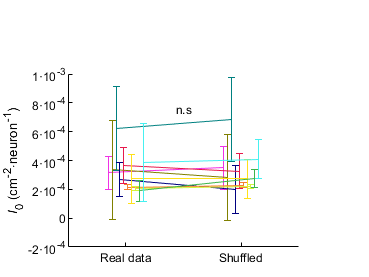

figure;
org.bns('I0', 'I0_s', true, false);
Utils.fix_exponent(gca,'y',0);
ylabel '{\itI}_0 (cm^{-2}\cdotneuron^{-1})'
figure_format([4 3]/2.5);
savefig('updated_figs/2g_effect_on_I0.fig');

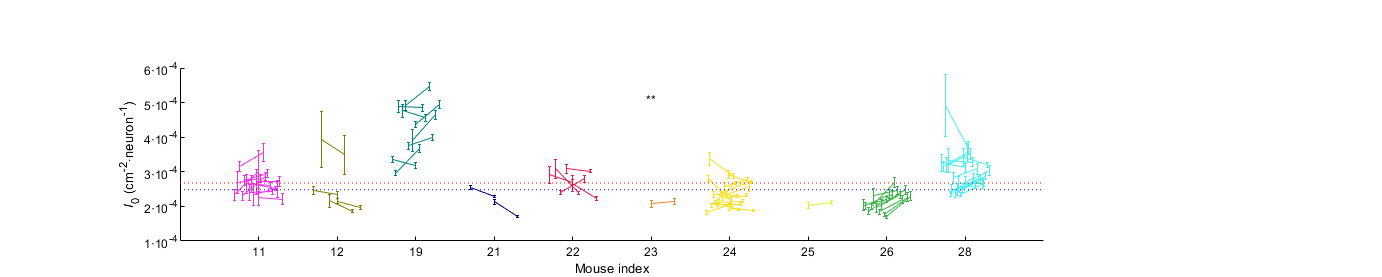

figure;
org.bns('I0', 'I0_s', false, false);
Utils.fix_exponent(gca,'y',0);
ylabel '{\itI}_0 (cm^{-2}\cdotneuron^{-1})'
xlabel 'Mouse index'
Utils.specific_format('MBNS');
savefig('updated_figs/2g_effect_on_I0_allsess.fig');

#### h - Effect on $I_0 N$

figure;
org.bns('I0N', 'I0N_s', true, true);

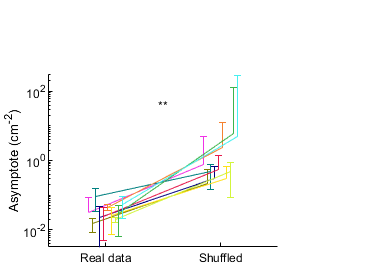

ylabel 'Asymptote (cm^{-2})'
ylim(10.^[-2.5 2.5]);
figure_format([4 3]/2.5);
savefig('updated_figs/2h_effect_on_I0N.fig');

figure;
org.bns('I0N', 'I0N_s', false, true);

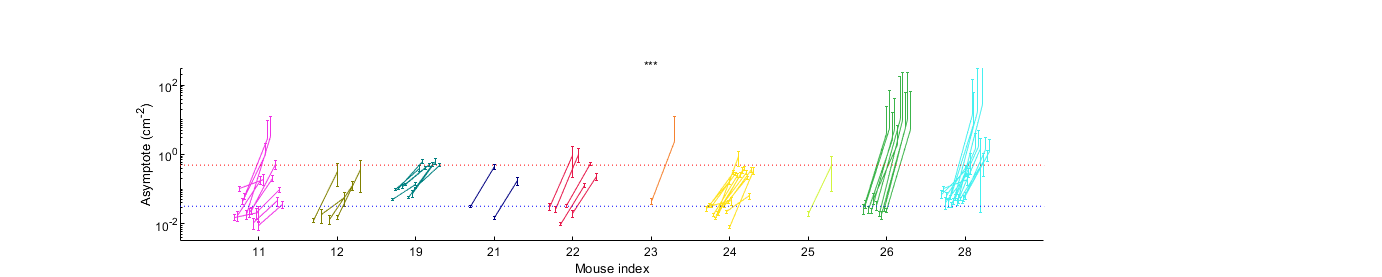

ylabel 'Asymptote (cm^{-2})'
ylim(10.^[-2.5 2.5]);
xlabel 'Mouse index'
Utils.specific_format('MBNS');
savefig('updated_figs/2h_effect_on_I0N_allsess.fig');

#### Effect on $N$

figure;
org.bns('N50', 'N50_s', true, true);

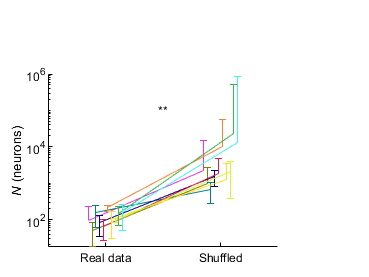

ylabel '{\itN} (neurons)'
%ylim(10.^[-2.5 2.5]);
figure_format([4 3]/2.5);
savefig('updated_figs/2_effect_on_N.fig');

figure;
org.bns('N50', 'N50_s', false, true);

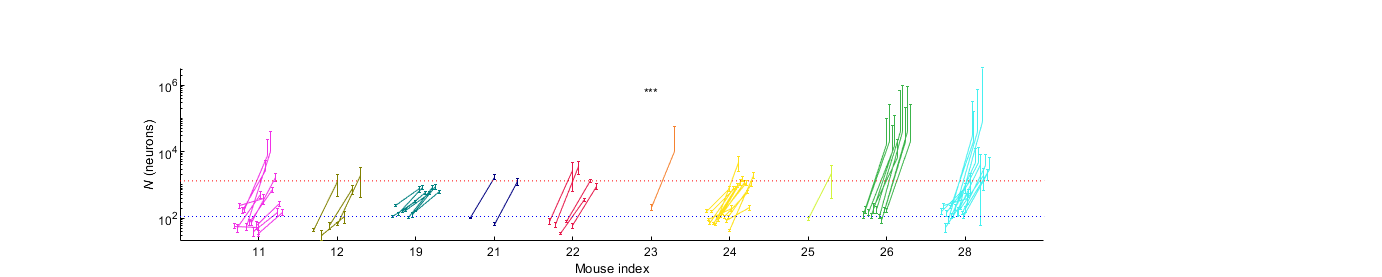

ylabel '{\itN} (neurons)'
%ylim(10.^[-2.5 2.5]);
xlabel 'Mouse index'
Utils.specific_format('MBNS');
savefig('updated_figs/2_effect_on_N_allsess.fig');

### Figure 3

#### f - Effect on asymptotic SNR

figure;
org.boxplot('asymp_snr', 'asymp_snr_shuf', true)
xlabel 'Mouse name'

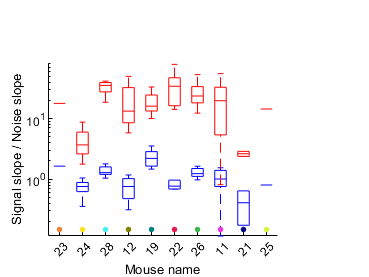

ylabel 'Signal slope / Noise slope'
figure_format([4 3]/2.5);


figure;
org.bns('asymp_snr', 'asymp_snr_shuf', true, true);

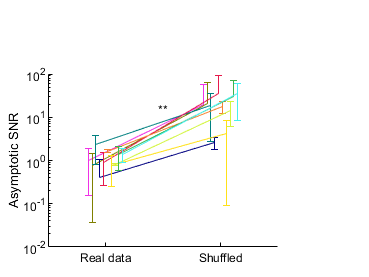

ylabel 'Asymptotic SNR'
figure_format([4 3]/2.5);
savefig('updated_figs/3f_effect_on_asymp_snr.fig');

figure;
org.bns('asymp_snr', 'asymp_snr_shuf', false, true);

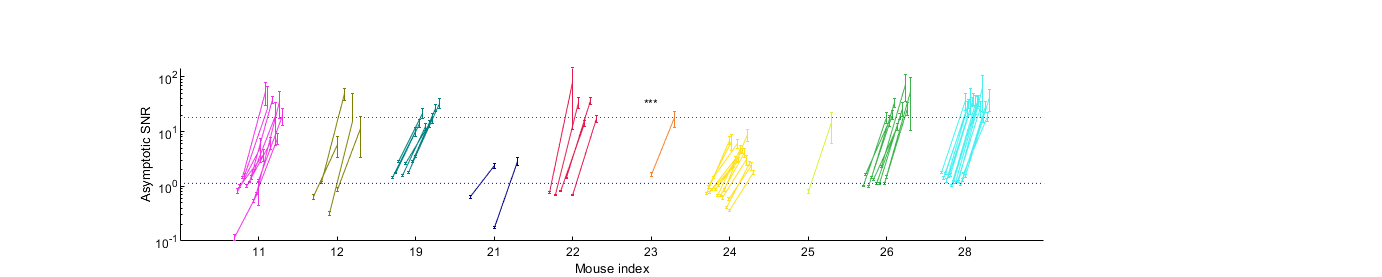

ylabel 'Asymptotic SNR'
xlabel 'Mouse index'
Utils.specific_format('MBNS');
savefig('updated_figs/3f_effect_on_asymp_snr_allsess.fig');

#### g - $I_0$ correspondence

figure;

org.correlogram('single_dp2', 'I0', true);

Using only 71 out of 107 sessions
Mouse-aggregated correlations single_dp2 vs. I0: adj. R^2 = 0.428
Pearson: 0.701, p = 2.393665e-02, *
Spearman: 0.067, p = 8.647535e-01, n.s
Kendall: 0.022, p = 1.000000e+00, n.s


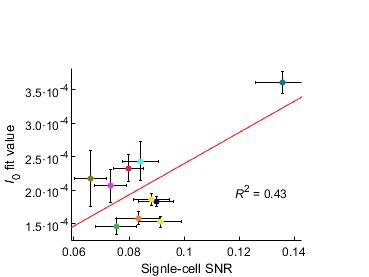

xlabel 'Signle-cell SNR'
ylabel '{\itI}_0 fit value'
Utils.fix_exponent(gca, 'y', 1);
figure_format([4 3]/2.5);
savefig('updated_figs/3g_I0_correspondence.fig');

figure;
org.correlogram('single_dp2', 'I0', false);

Using only 71 out of 107 sessions
Sessionwise correlations single_dp2 vs. I0: adj. R^2 = 0.426
Pearson: 0.659, p = 4.230067e-10, ***
Spearman: 0.480, p = 2.236031e-05, ***
Kendall: 0.331, p = 4.597673e-05, ***


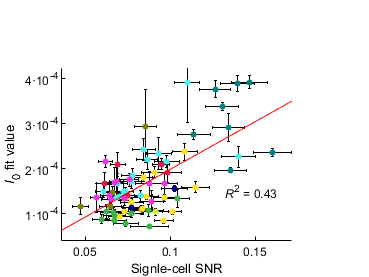

xlabel 'Signle-cell SNR'
ylabel '{\itI}_0 fit value'
Utils.fix_exponent(gca, 'y', 0);
figure_format([4 3]/2.5);
savefig('updated_figs/3g_I0_correspondence_allsess.fig');

#### h - Asymptotic correspondence

figure;
org.correlogram('asymp_snr', 'I0N', true);

Using only 71 out of 107 sessions
Mouse-aggregated correlations asymp_snr vs. I0N: adj. R^2 = 0.794
Pearson: 0.904, p = 3.323948e-04, ***
Spearman: 0.891, p = 1.380267e-03, **
Kendall: 0.733, p = 2.212853e-03, **


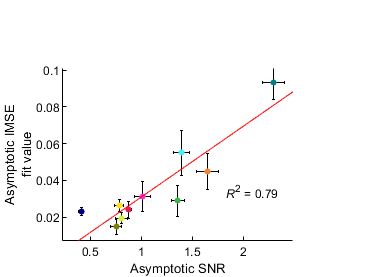

xlabel 'Asymptotic SNR'
ylabel(sprintf('Asymptotic IMSE\nfit value'));
figure_format([4 3]/2.5);
savefig('updated_figs/3h_I0N_correspondence.fig');

figure;
org.correlogram('asymp_snr', 'I0N', false);

Using only 71 out of 107 sessions
Sessionwise correlations asymp_snr vs. I0N: adj. R^2 = 0.453
Pearson: 0.679, p = 7.857710e-11, ***
Spearman: 0.650, p = 8.453635e-10, ***
Kendall: 0.469, p = 7.797761e-09, ***


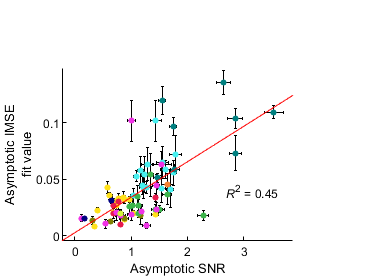

xlabel 'Asymptotic SNR'
ylabel(sprintf('Asymptotic IMSE\nfit value'));
figure_format([4 3]/2.5);
savefig('updated_figs/3h_I0N_correspondence_allsess.fig');

#### k (proposed) - Area between curves effect on $N_{50}$ (real - shuffled, up to PC10)

figure;
org.correlogram('delta_cos2_area_10', 'invN50', true);

Using only 71 out of 107 sessions
Mouse-aggregated correlations delta_cos2_area_10 vs. invN50: adj. R^2 = 0.608
Pearson: 0.807, p = 4.731966e-03, **
Spearman: 0.782, p = 1.165127e-02, *
Kendall: 0.644, p = 9.148479e-03, **


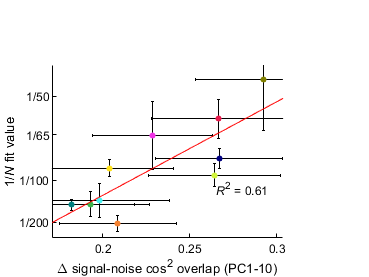

xlabel '\Delta signal-noise cos^2 overlap (PC1-10)'
ylabel '1/{\itN} fit value'
Nvals = [200 100 65 50];
Nlabels = arrayfun(@(x)['1/' num2str(x)],Nvals,'UniformOutput',false);
set(gca, 'YTick', 1./Nvals);
set(gca, 'YTickLabels', Nlabels);
figure_format([4 3]/2.5);
savefig('updated_figs/3k_N_correspondence.fig');

figure;
org.correlogram('delta_cos2_area_10', 'invN50', false);

Using only 71 out of 107 sessions
Sessionwise correlations delta_cos2_area_10 vs. invN50: adj. R^2 = 0.218
Pearson: 0.479, p = 2.403883e-05, ***
Spearman: 0.406, p = 4.381538e-04, ***
Kendall: 0.281, p = 5.407923e-04, ***


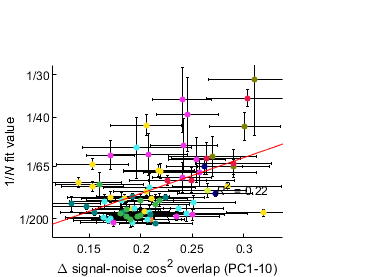

xlabel '\Delta signal-noise cos^2 overlap (PC1-10)'
ylabel '1/{\itN} fit value'
Nvals = [200 65 40 30];
Nlabels = arrayfun(@(x)['1/' num2str(x)],Nvals,'UniformOutput',false);
set(gca, 'YTick', 1./Nvals);
set(gca, 'YTickLabels', Nlabels);
figure_format([4 3]/2.5);
savefig('updated_figs/3k_N_correspondence_allsess.fig');

### Figure 4

#### h - Signal density and asymptotic ratio

figure;
org.correlogram('signal_density', 'asymp_ratio', true);

Using only 71 out of 107 sessions
Mouse-aggregated correlations signal_density vs. asymp_ratio: adj. R^2 = 0.930
Pearson: -0.968, p = 4.195672e-06, ***
Spearman: -0.976, p = 0.000000e+00, ***
Kendall: -0.911, p = 2.976190e-05, ***


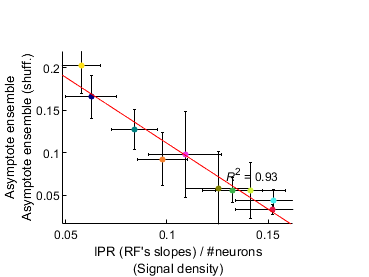

xlabel(sprintf('IPR (RF''s slopes) / #neurons\n(Signal density)'));
ylabel(sprintf('Asymptote ensemble\nAsymptote ensemble (shuff.)'));
figure_format([4 3]/2.5);
savefig('updated_figs/4h_signal_density.fig');

figure;
org.correlogram('signal_density', 'asymp_ratio', false);

Using only 71 out of 107 sessions
Sessionwise correlations signal_density vs. asymp_ratio: adj. R^2 = 0.607
Pearson: -0.783, p = 7.684910e-16, ***
Spearman: -0.840, p = 0.000000e+00, ***
Kendall: -0.652, p = 9.656072e-16, ***


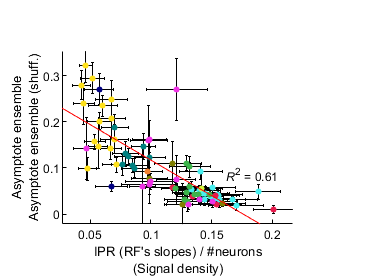

xlabel(sprintf('IPR (RF''s slopes) / #neurons\n(Signal density)'));
ylabel(sprintf('Asymptote ensemble\nAsymptote ensemble (shuff.)'));
figure_format([4 3]/2.5);
savefig('updated_figs/4h_signal_density_allsess.fig');